Import File Stl hoặc Step cho mô hình

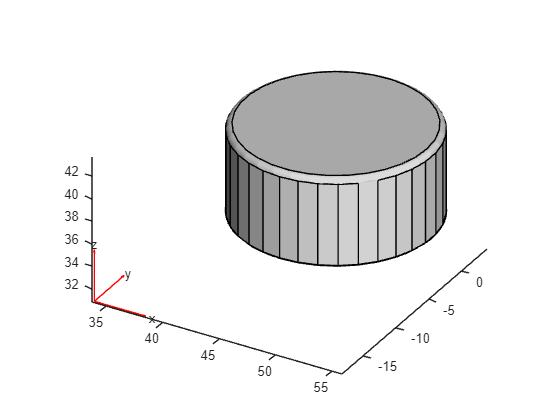

gm = importGeometry("cau_truc\break_disk\Brake_Piston_1.stl");
pdegplot(gm);

Tạo 

gm = fegeometry(gm)

gm =   fegeometry with properties:

       NumFaces: 113
       NumEdges: 287
    NumVertices: 180
       NumCells: 1
       Vertices: [180×3 double]
           Mesh: []


Tạo Mesh

model = createpde;
geometryFromMesh(model,nodes,elements);

Unrecognized function or variable 'nodes'.

pdegplot3D(gm,"CellLabels","on","FaceAlpha",0.5)

Tạo

gm = importGeometry("cau_truc\Brake_Piston_1.stl");
gm = generateMesh(gm);
gm.Mesh

Plot the Mesh

pdemesh(gm);